# Processing Data Samples from MRI

## Get a sample from the chest aim the radar at your chest

Library is already loaded.

Functions in library libModuleConnector64:

data_reader_at_end                    nva_get_respiration_data              nva_set_x4_io_pin_mode                
data_reader_close                     nva_get_serial_number                 nva_set_x4_io_pin_value               
data_reader_create                    nva_get_sleep_data                    nva_start_recording                   
data_reader_destroy                   nva_get_system_info                   nva_stop_recording                    
data_reader_get_data_types            nva_get_trace                         nva_subscribe                         
data_reader_get_duration              nva_get_x2                            nva_subscribe_to_baseband_ap          
data_reader_get_filter                nva_get_x2_float                      nva_subscribe_to_baseband_iq          
data_reader_get_max_record_size       nva_get_x2_int                        nva_subscribe_to_data_byte            
data_rea

Packets available: 0
Packets available: 1
Packets available: 0
Packets available: 0
Packets available: 0
Packets available: 0
Packets available: 0
Packets available: 0
Packets available: 0
Packets available: 0
Packets available: 0
Packets available: 0
Packets available: 0
Packets available: 0
Packets available: 0
Packets available: 0
Packets available: 0
Packets available: 0
Read 1800 frames. A total of 1800 were sent from chip. Frames dropped: 0
Estimated FPS: 59.974, should be: 60
Closing radar


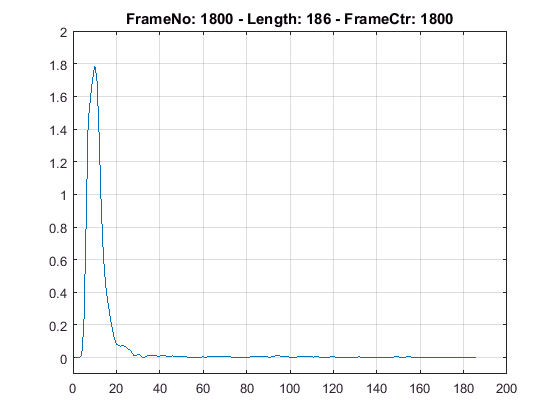

FPS = 60.0;
Duration = 30.0; % Seconds
raw_chest_sample = acquire_radar_data(FPS, Duration);

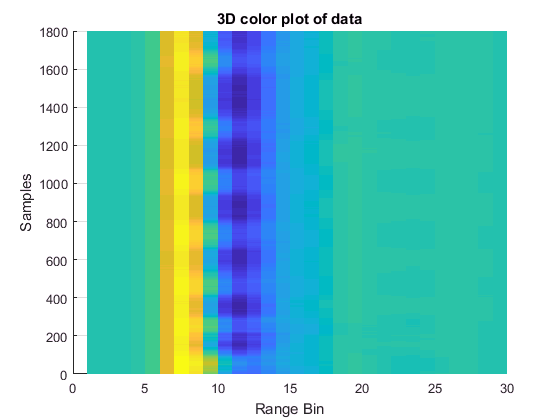

% Drawing raw data unprocessed
figure(1);
raw_chest_sample_real = real(raw_chest_sample);
surf(raw_chest_sample_real(1:end, 1:30), 'EdgeColor', 'None');
title('3D color plot of data');
view(2);
xlabel('Range Bin')
ylabel('Samples')

figure(2);

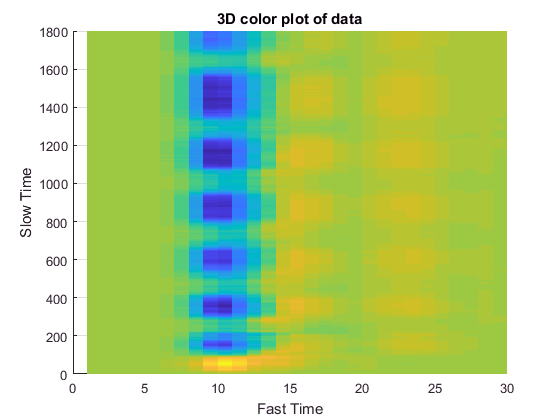

% Removing the offset of the radar sent information
[slowTime, fastTime] = size(raw_chest_sample);
chest_sample = zeros(slowTime, fastTime);
zero_sample = raw_chest_sample(1,:);
for i=1:slowTime
    chest_sample(i,:) = raw_chest_sample(i,:) - zero_sample;
end
chest_sample_real = real(chest_sample);
surf(chest_sample_real(1:end, 1:30), 'EdgeColor', 'None');
title('3D color plot of data');
xlabel('Fast Time')
ylabel('Slow Time')
view(2);

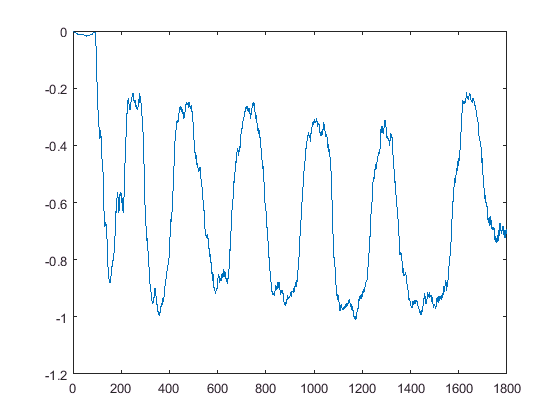

% Calculating Respiratory Rate from the 3D plot by finding the lowest point
% at a certain time and find the positions for that lowest time
lowest_time = zeros(slowTime, 0);
lowest_point = zeros(slowTime, 0);
for i = 1:slowTime
   [lowest_point(i), lowest_time(i)] = min(chest_sample_real(i,1:30));
end
plot(real(lowest_point));

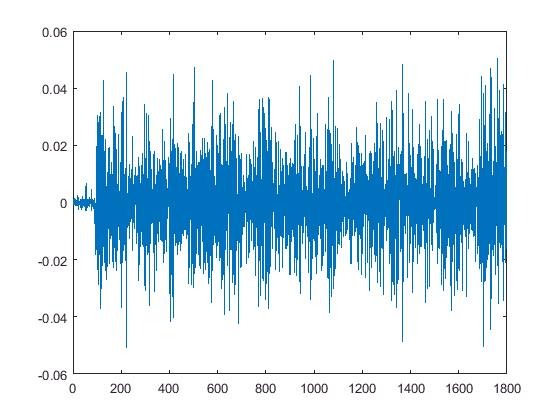


% Acceleration
plot(diff(diff(real(lowest_point))));

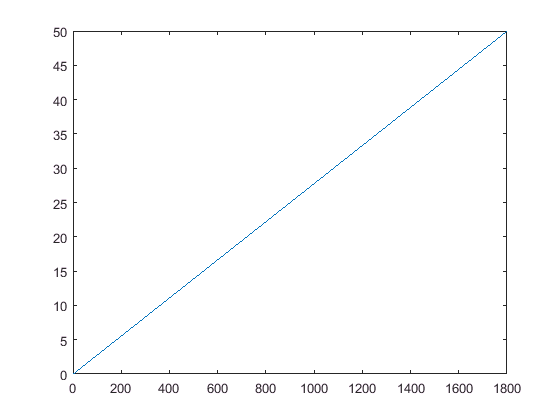


% Fourier Transform
lowest_point_fft = fft(lowest_point);
lowest_point_fft_abs = abs(lowest_point_fft);
freq_vector = (0:length(lowest_point_fft)-1)*50/length(lowest_point_fft);
plot(freq_vector, lowest_point_fft);

## Modelling

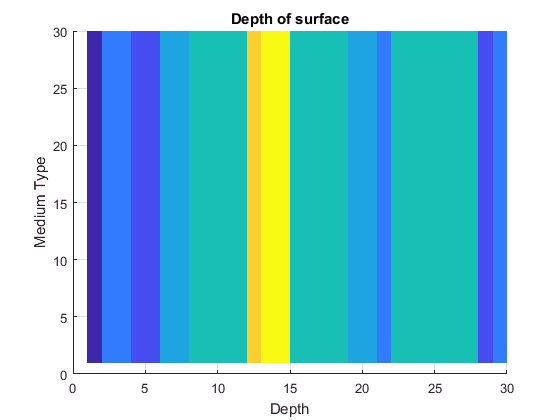

% Load the 3D chest sample

% Create a fake 2D chest sample from the 3D sample
chest_model = zeros(30, 30, 30);
chest_model(:,1:1,:) = 1;        % Clothes front
chest_model(:,2:3,:) = 3;        % Skin
chest_model(:,4:5,:) = 2;        % Fat
chest_model(:,6:7,:) = 4;        % Muscle
chest_model(:,8:11,:) = 5;        % Bone
chest_model(:,12:12,:) = 8;        % Fat
chest_model(:,13:14,:) = 9;        % Heart-muscle
chest_model(:,15:18,:) = 5;        % Blood
chest_model(:,19:20,:) = 4;        % Heart-muscle
chest_model(:,21:21,:) = 3;        % Fat
chest_model(:,22:27,:) = 5;        % Lung
chest_model(:,28:28,:) = 2;        % Bone
chest_model(:,29:29,:) = 3;        % Muscle
chest_model(:,30:30,:) = 4;        % Fat
surf(chest_model(:,:,1), 'EdgeColor', 'None');
view(2);
title('Depth of surface')
xlabel('Depth')
ylabel('Medium Type')